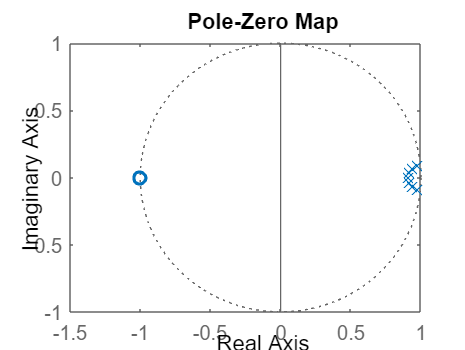

%slip7
Fs=720;
[N,wn]=buttord(10*2/Fs,20*2/Fs,3,40);
[B,A]=butter(N,wn);
SYS=tf(B,A,1/Fs);
figure();
pzmap(SYS);

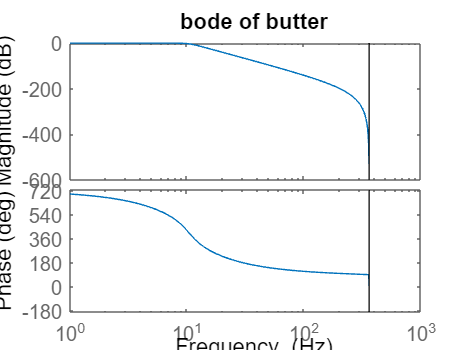


figure();
h=bodeplot(SYS);
setoptions(h,'FreqUnits','Hz');
title('bode of butter');